## Diffusion

### Fully Implicit: can it find a good equilibrium

% Large time step
% Stability factor: kappa*tau/h^2
% FTCS stable for factors < 1/2
stabilityFactor = 20;
diffusion_fimp(stabilityFactor)

% Larger time step
stabilityFactor = 100; % FTCS stable for factors < 1/2
diffusion_fimp(stabilityFactor)

% Very large time step
stabilityFactor = 500; % FTCS stable for factors < 1/2
diffusion_fimp(stabilityFactor)

### Comparison to FTCS:

stabilityFactor = 0.5; % Max time step for stability
diffusion_ftcs_leftRightBoundary(stabilityFactor,'right')

% Can we push up the time step a little to make it converge faster?
stabilityFactor = 0.51;
diffusion_ftcs_leftRightBoundary(stabilityFactor,'right')

### Crank-Nicolson

FTCS stability factor (stable <= 1/2): 0.5


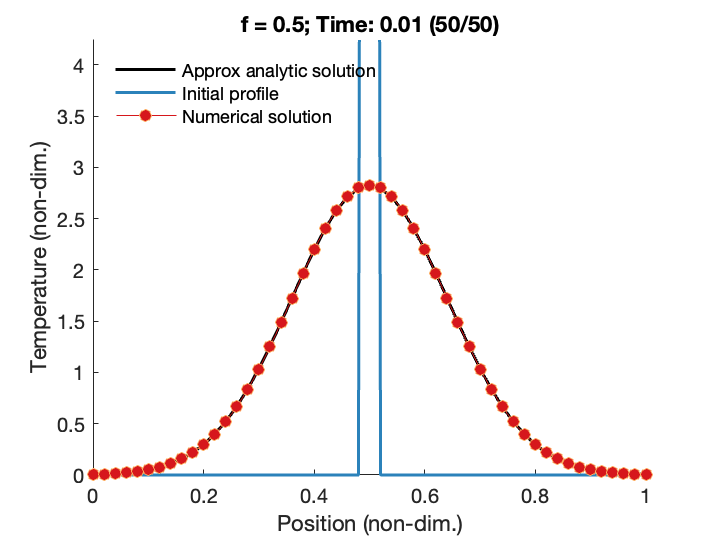

% FTCS stability factor at max for FTCS (factor 0.5)
tau = 2e-4;
h = 0.02;
diffusion_cnic(tau,h)

FTCS stability factor (stable <= 1/2): 10


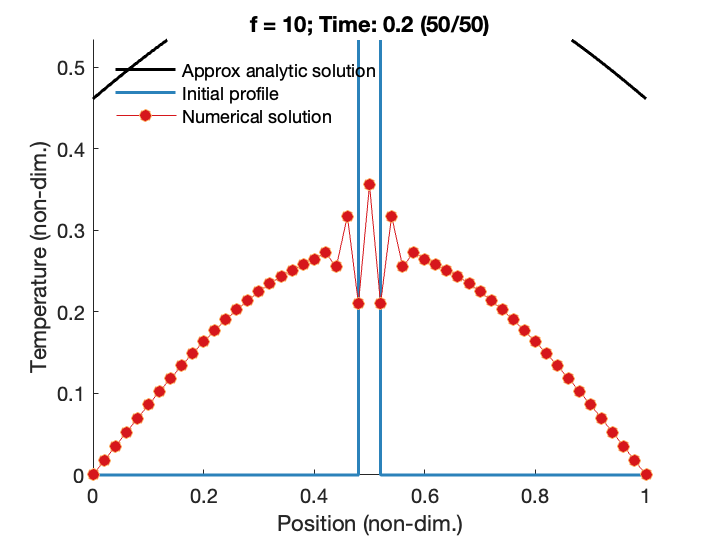

% Monster time step (factor 5)
tau = 4e-3;
h = 0.02;
diffusion_cnic(tau,h)